# DEMO UNIT MATCH

% Example data can be found here: https://doi.org/10.6084/m9.figshare.24305758.v1

## README

% UnitMatch matches neurons within and across days using only their spatiotemporal waveforms.
% To run, it needs a folder called 'RawWaveforms' for each recording, where there should be a NPY file for every cluster
% containing the average waveform (recommended of at least 500 spikes) for every recording channel
% for every half of a recording for that cluster (spikeWidth x nRecordingChannels x 2).

% If you use spikeGLX or OpenEphys, the UnitMatch pipeline will extract those waveforms for you (using ExtractAndSaveAverageWaveforms.m).

## -- Preprocessing ---

% First, let's preprocess the data.

## Add required and optional paths and subpaths

GithubDir = 'C:\Users\user_name\Documents\GitHub'; % Github directory

% Required (for using UnitMatch):
addpath(genpath(fullfile(GithubDir,'spikes'))) % https://github.com/cortex-lab/spikes
addpath(genpath(fullfile(GithubDir,'npy-matlab'))) % https://github.com/kwikteam/npy-matlab
addpath(genpath(fullfile(GithubDir,'mtscomp'))) % https://github.com/int-brain-lab/mtscomp

% Advised (quality metrics for unit selection):
addpath(genpath(fullfile(GithubDir,'bombcell'))) % DOI: 10.5281/zenodo.8172822, https://github.com/Julie-Fabre/bombcell

% UNITMATCH - Move to top of paths
addpath(genpath(fullfile(GithubDir,'UnitMatch'))) % Make sure to have this one fresh in the path (so run this last)

## User input

% This is the path where the results will be saved ('\\path\to\save\UnitMatch'), e.g.:
UMparam.SaveDir = "C:\Users\klein\OneDrive\summer_intern\tmp";

% This is a cell array with a path to each recording's Kilosort output directory, where there should be a subfolder called 'RawWaveforms'.
% N.B. if you want to use the functional score evaluation of UnitMatch, 'KSDir' should also contain the Kilosort output (e.g. spike times etc.)/
% Takes the form of "{'\\path\to\firstrecording','\\path\to\secondrecording','\\path\to\nthrecording'};", e.g.:

% UMparam.KSDir = {'D:\Univ\25spring\summer_intern\tmp_data\demo_data\Mouse1\AL032\2019-11-21\Probe0\1','D:\Univ\25spring\summer_intern\tmp_data\demo_data\Mouse1\AL032\2019-11-22\Probe0\1'};
UMparam.KSDir = {"E:\Dropbox_transfer\Neuropixels\9153\01302025\kilosort4","E:\Dropbox_transfer\Neuropixels\9153\01312025\kilosort4"};

## Get recording information

% In this part, you will provide the paths for the raw data, and the channel position, for each recording.


% -- IF USING KILOSORT --

% If you use Kilosort, you can use the following. It extracts KS data and do some noise removal,
% and will generate a "PreparedData.mat" file that will be useful in the next section.
% RawDataPaths and AllChannelPos will be found automatically, but please
% note data dat_path in params.py should be accurate. Otherwise, please
% define: 
% UMparam.RawDataPaths = {'D:\Univ\25spring\summer_intern\tmp_data\demo_data\Mouse1\AL032\2019-11-21\Probe0\1\RawWaveforms','D:\Univ\25spring\summer_intern\tmp_data\demo_data\Mouse1\AL032\2019-11-22\Probe0\1\RawWaveforms'};
UMparam.RawDataPaths = {"E:\Dropbox_transfer\Neuropixels\9153\01302025\9153_01302025_tagging_g0_tcat.imec0.ap.bin", "E:\Dropbox_transfer\Neuropixels\9153\01312025\9153_01312025_tagging_g0_tcat.imec0.ap.bin"};
RawDataPaths = {"E:\Dropbox_transfer\Neuropixels\9153\01302025\9153_01302025_tagging_g0_tcat.imec0.ap.bin", "E:\Dropbox_transfer\Neuropixels\9153\01312025\9153_01312025_tagging_g0_tcat.imec0.ap.bin"};
% % A cell array with info on where to find the decompressed recording (.bin files) -- typically a temporary folder:
UMparam.AllDecompPaths = {"E:\Dropbox_transfer\Neuropixels\9153\01302025\9153_01302025_tagging_g0_tcat.imec0.ap.bin", "E:\Dropbox_transfer\Neuropixels\9153\01312025\9153_01312025_tagging_g0_tcat.imec0.ap.bin"};
% Optionally, it will decompresse cbin to bin data and can use BOMBCELL quality metric to define good single units.
UMparam.RunQualityMetrics = 0; % This assumes you run Bombcell, if not please set this to 0.
% For other Default parameters, please see
% DefaultParametersExtractKSData.m. Specifify all UMparam that should be
% different from the default before running ExtractKilosortData
UMparam = ExtractKilosortData(UMparam.KSDir, UMparam, RawDataPaths);

    "Found existing data in "    "E:\Dropbox_transfer\Neuropixels\9153\01302025\kilosort4"    ", Using this..."

    "Found existing data in "    "E:\Dropbox_transfer\Neuropixels\9153\01312025\kilosort4"    ", Using this..."




% You can also force the raw data paths as a 3rd argument: UMparam = ExtractKilosortData(KiloSortPaths, UMparam, RawDataPaths);
% If RawDataPaths is not given, raw data path will be obtained from Kilosort's output file "params.py".

% -- IF NOT --
% You can generate those:
% % A cell array with info on where to find or store the compressed recording (.cbin files OR .bin files):
% UMparam.RawDataPaths = {'\\path\to\firstrecording.cbin','\\path\to\secondrecording.cbin','\\path\to\nthrecording.cbin'};
% % A cell array with info on where to find the decompressed recording (.bin files) -- typically a temporary folder:
% UMparam.AllDecompPaths = {'\\path\to\firstrecording.bin','\\path\to\secondrecording.bin','\\path\to\nthrecording.bin'};
% % The coordinates of every recording channel on the probe (e.g. nRecordingChannels x 2), in the same order as the channels were recorded:
% UMparam.AllChannelPos = {[RecordingSites_Recording1],[RecordingSites_Recording2]};

## Get cluster information

% -- IF USING KILOSORT --

% If you use kilosort and have used "ExtractKilosortData" above to generate the "PreparedData.mat" files, you can use:
clusinfo = getClusinfo(UMparam.KSDir);

    "Loading clusinfo for "    "E:\Dropbox_transfer\Neuropixels\9153\01302025\kilosort4"

    "Loading clusinfo for "    "E:\Dropbox_transfer\Neuropixels\9153\01312025\kilosort4"




% -- IF NOT --
% In this part, you will have to generate "clusinfo", a structure that contains basic information about the clusters:
% * cluster_id (e.g. kilosort output clus_id)
% * Good_ID: ones for units that should be included in the analysis (typically well isolated single units)
% * RecSesID: Recording Session ID
% * Probe: Which probe (if just 1, ones of numel cluster_id)
% * Depth: depth on probe (optional)
% * Shank: Which shank (optional)

## -- Running UnitMatch --

% Now, we can run UnitMatch.
% (Note that waveform extraction will take place in UnitMatch.m if not performed before)

## Load default parameters:

UMparam.[xxxx] = xx % Specificy all parameters that should be different form the default before you run DefaultParametersUnitMatch.

UMparam = DefaultParametersUnitMatch(UMparam);

## UnitMatch algorithm:

Scores2Include = 1×6 cell 数组
    {'CentroidDist'}    {'WavformSim'}    {'CentroidOverlord'}    {'spatialdecaySim'}    {'AmplitudeSim'}    {'LocTrajectorySim'}


Extracting raw waveforms. Progress: 100%
Extracting raw waveforms took 0 minutes for 481 units
Extracting waveform information. Progress: 100%
Extracting raw waveforms and parameters took 9.6984 seconds for 481 units
Computing location distances between pairs of units...
Computing Metric similarity between pairs of units...
Computing waveform similarity between pairs of units...
Calculating waveform similarity took 0 seconds for 481 units
Computing location distances between pairs of units, per individual time point of the waveform...
Computing location distances between pairs of units, per individual time point of the waveform, Recentered...
Computing location angle (direction) differences between pairs of units, per individual time point of the waveform...
Extracting projected location took 1.8687 seconds for 481 units
Computing total score...
Median drift recording 1 calculated: X=0, Y=0.20712, Z=-5.9477


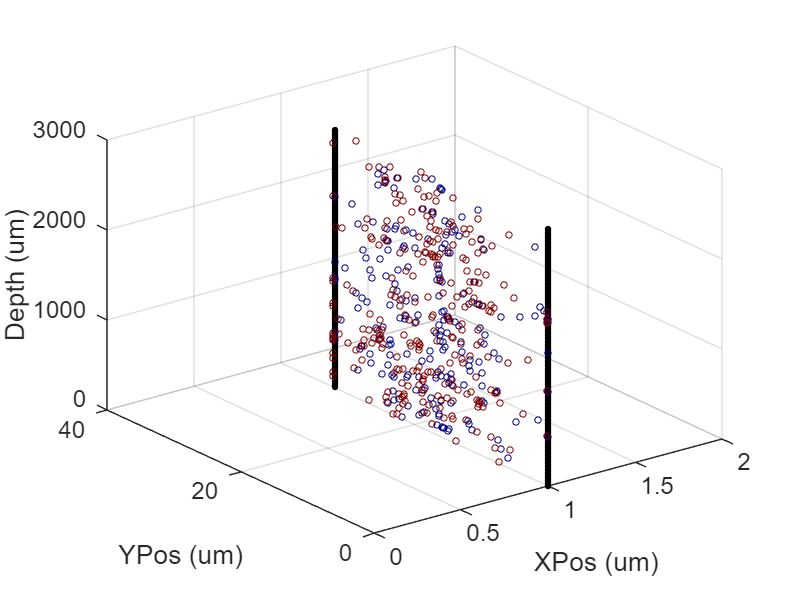

Computing location distances between pairs of units, per individual time point of the waveform...
Computing location distances between pairs of units, per individual time point of the waveform, Recentered...
Computing location angle (direction) differences between pairs of units, per individual time point of the waveform...


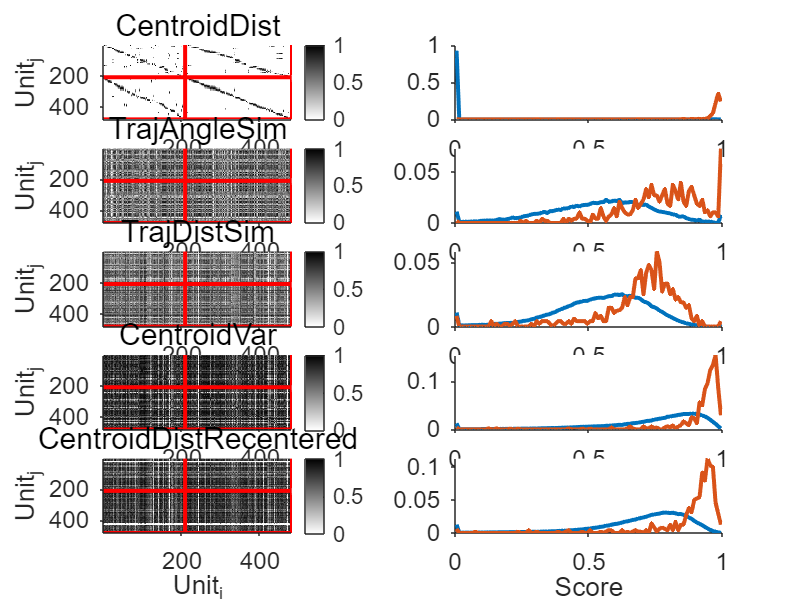

Extracting projected location took 3.4201 seconds for 481 units


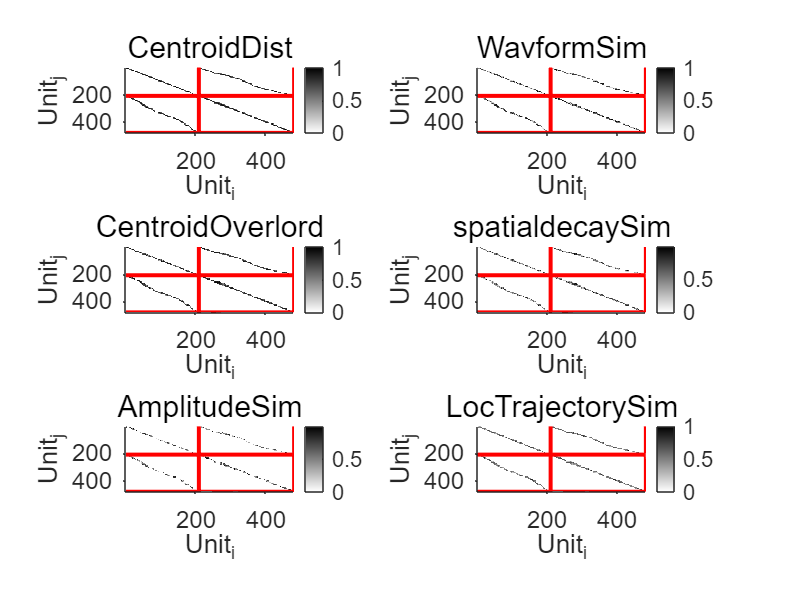

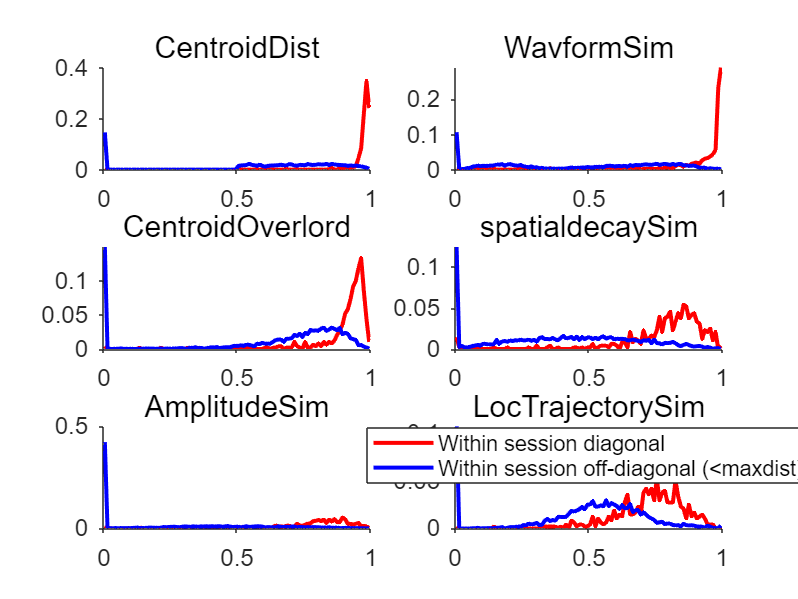

Computing total score...


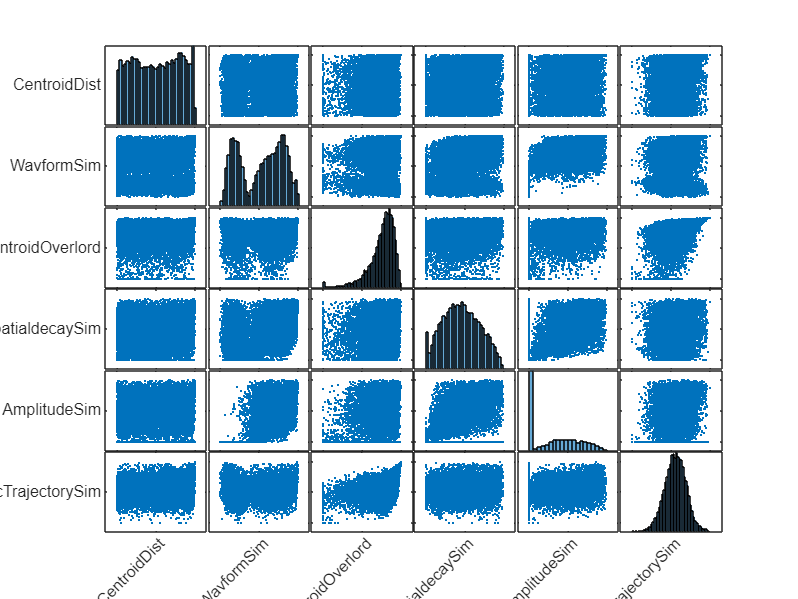

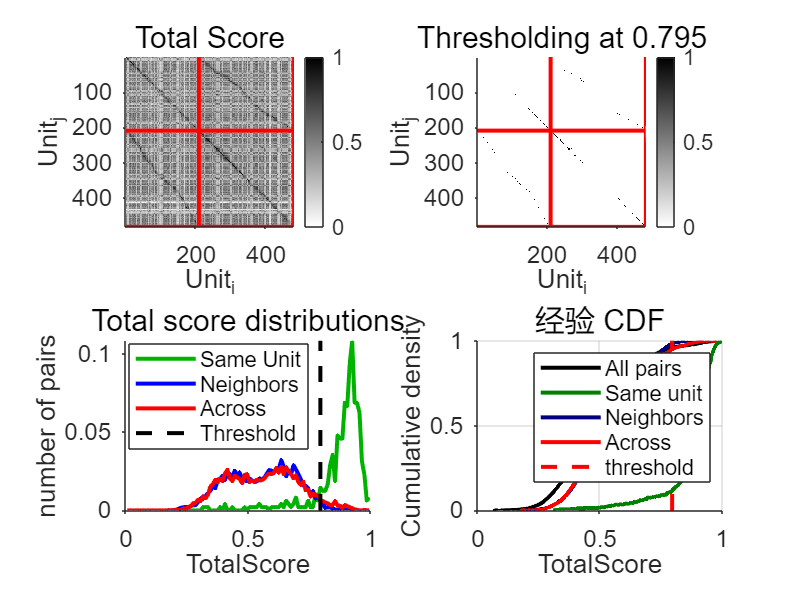

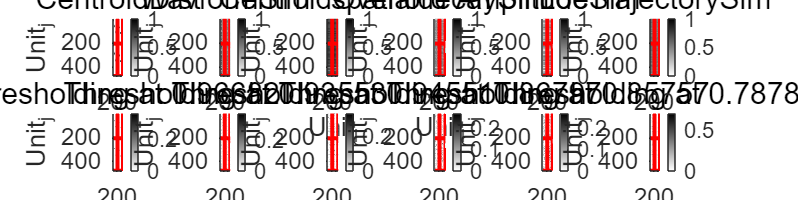

Median drift recording 1 calculated: X=0, Y=0, Z=-1.24


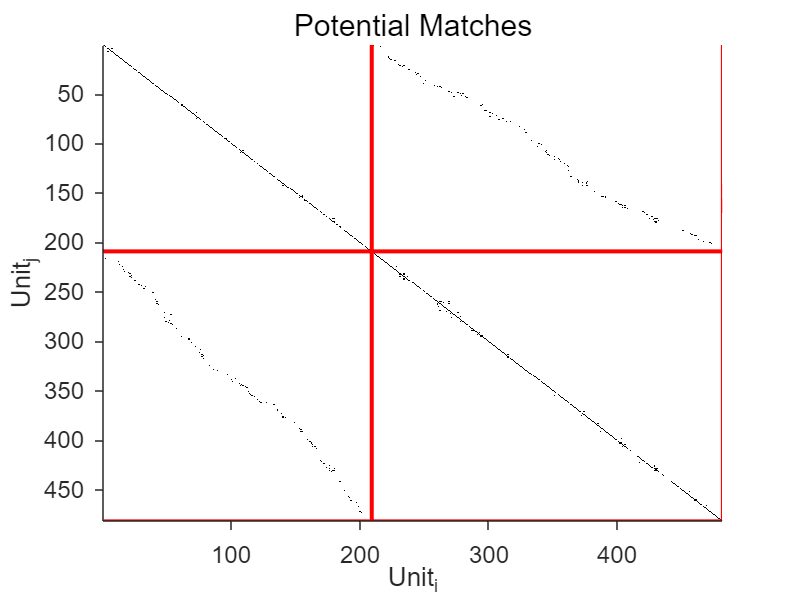

priorMatch = 0.9969

Creating the Naive Bayes model...
Average cross-validation match = 0 performance: 100%
Average cross-validation match = 1 performance: 95.5%
Done in 1s.
Getting the Naive Bayes model took 3.6597 seconds for 481 units
Extracting final pairs of units...


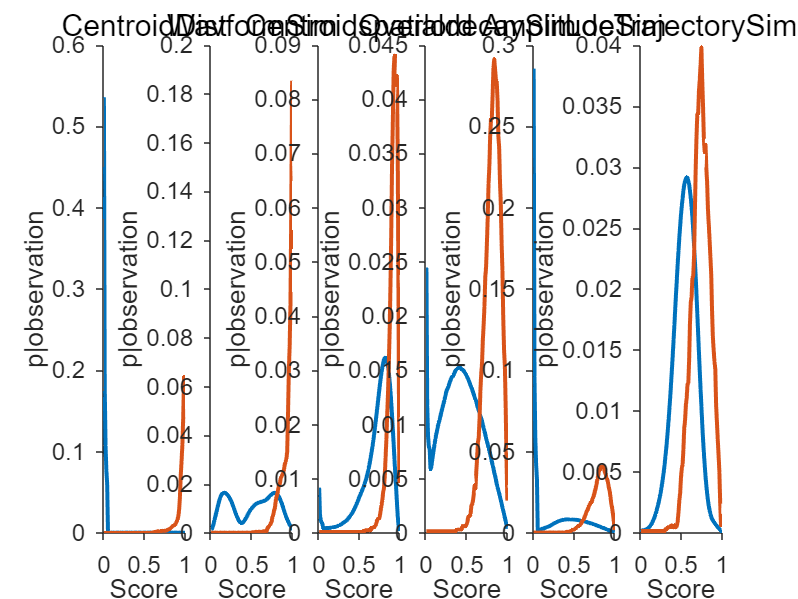

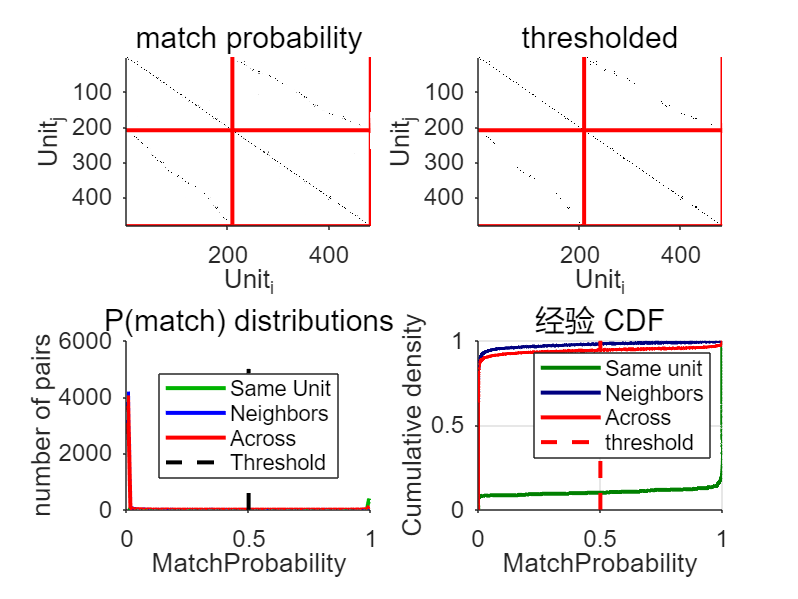

Extracting final pair of units took 2.1981 seconds for 481 units
Evaluating Naive Bayes...
90% of units were matched with itself
False negative estimate: 10.4%


False positive estimate recording 1: 0.82%
False positive estimate recording 2: 1.04%


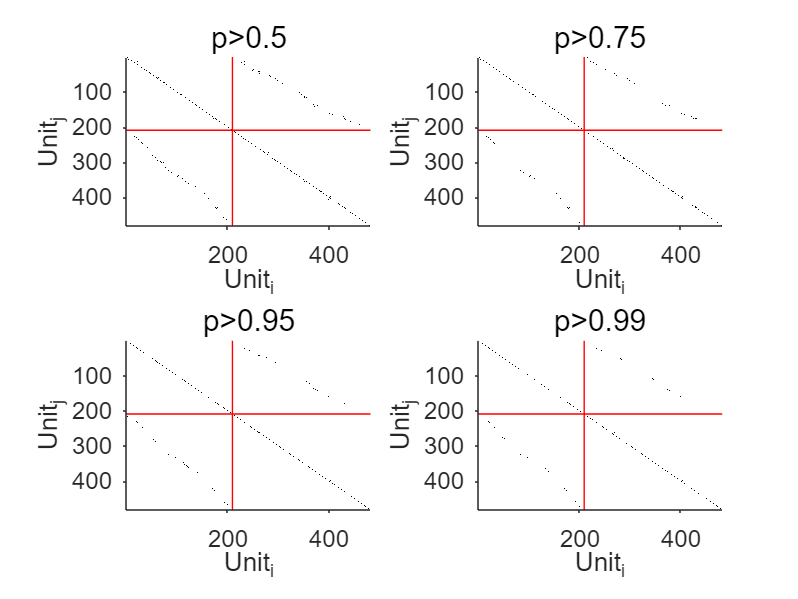

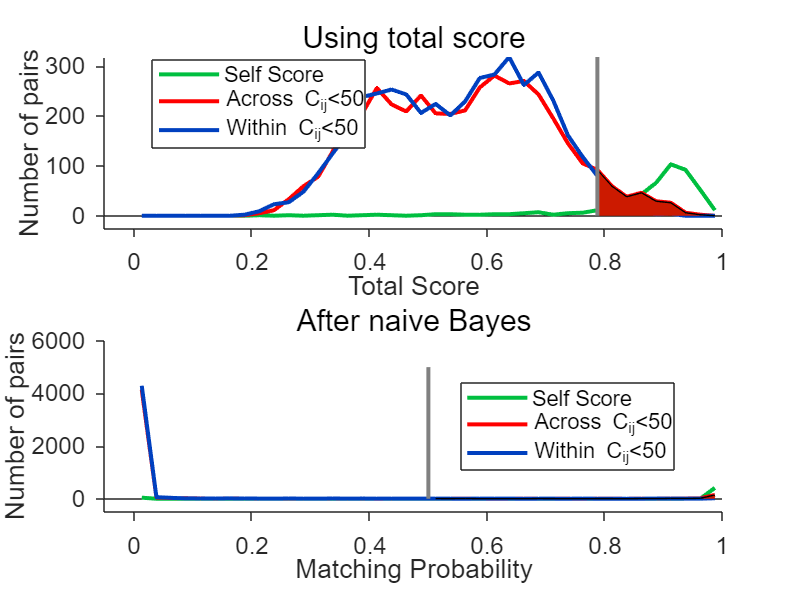

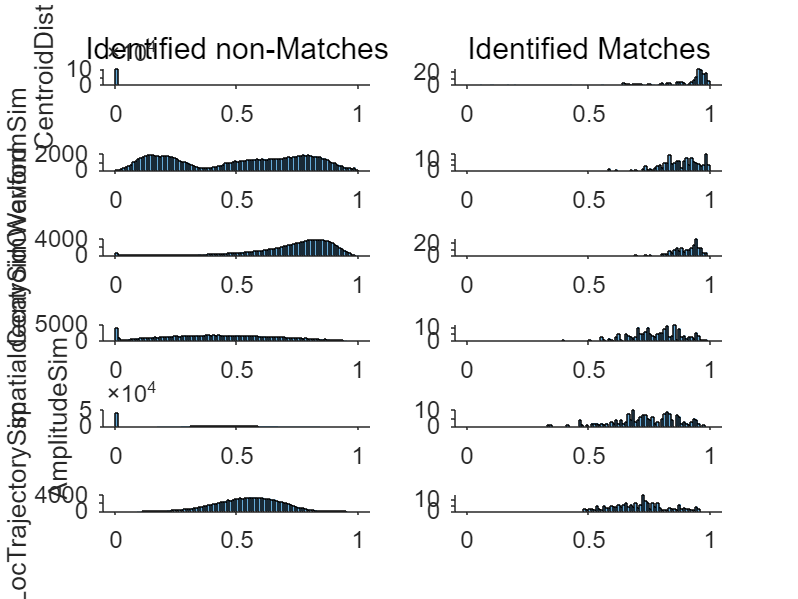

% Obtain the probability for each pair of units of being a "match"
[UniqueIDConversion, MatchTable, WaveformInfo, UMparam] = UnitMatch(clusinfo, UMparam);


% Apply tracking algoritms based on UnitMatch's output probabilities
if UMparam.AssignUniqueID
    [UniqueIDConversion, MatchTable] = AssignUniqueID(UMparam.SaveDir);
end

Loading match table to assign Unique IDs...
Assigning correct Unique ID values now
Used Probability = 0.85
Assigning pairs. Progress: 100%91 liberal matches/481
81 conservative matches/481
81 intermediate matches/481
Saving table


## -- Evaluating the output -- (optional)

## If you want, you can run additional scripts to evaluate the results:

Evaluating the model as it was ran by user


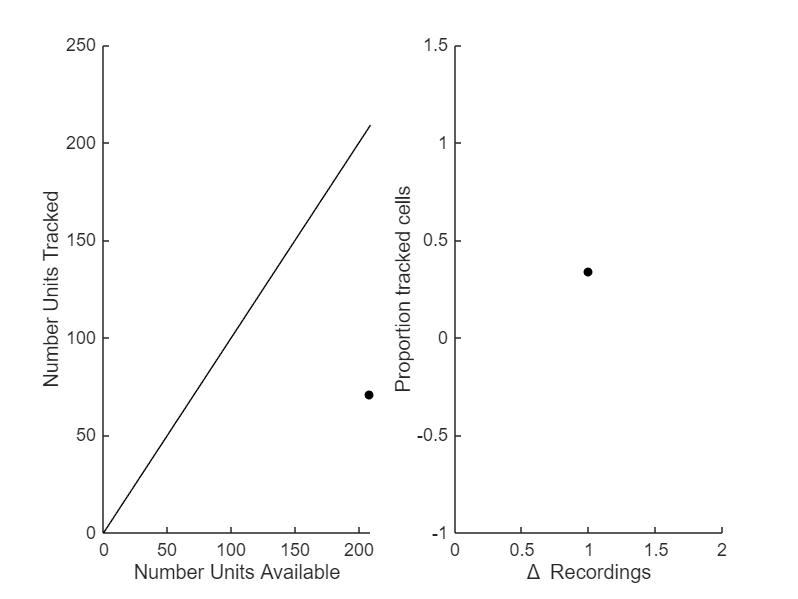

Within recording cross-validation: PyKS was ran on individual sessions


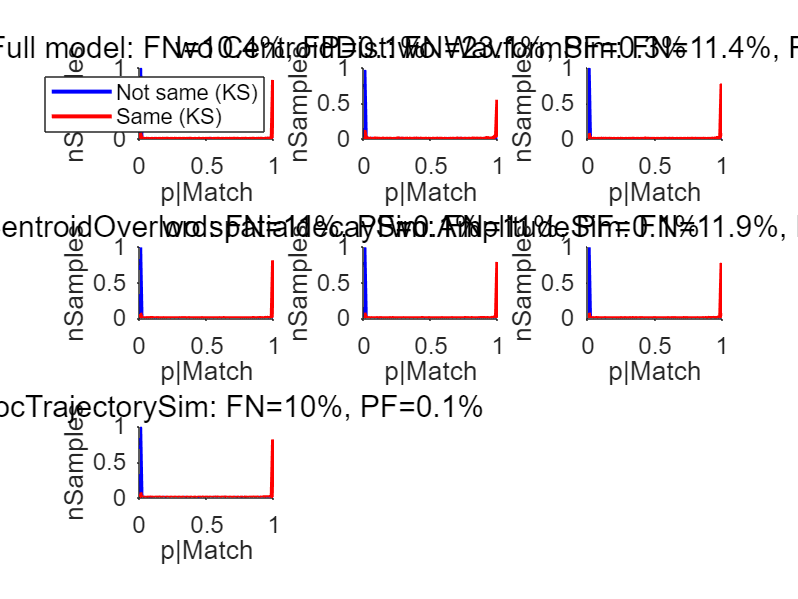

False negative rate: 10.4%
False positive rate: 0.1%
We advise to use the model you just used on this data:
This parameter set is probably the best


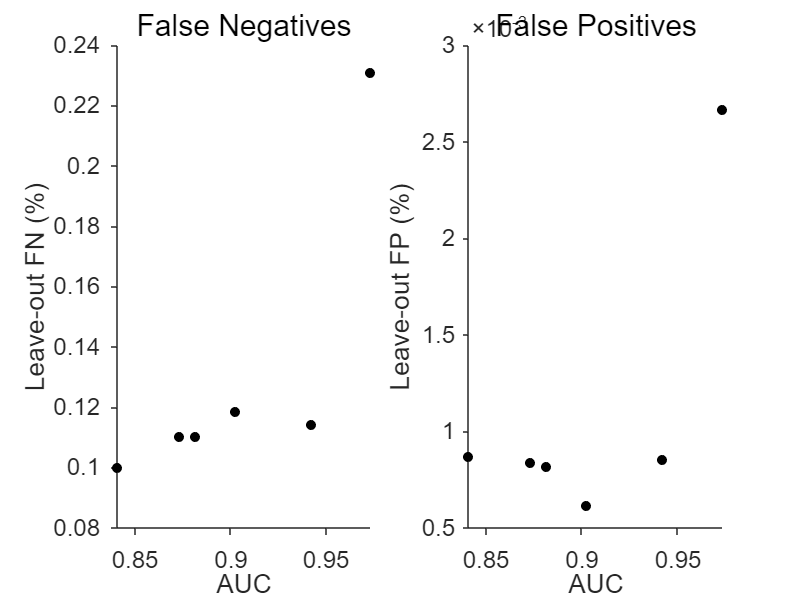

AUC order:


ans = 1×13 cell 数组
    {'CentroidDist'}    {'WavformSim'}    {'WavformMSE'}    {'WVCorr'}    {'AmplitudeSim'}    {'spatialdecaySim'}    {'CentroidDistRecentered'}    {'CentroidOverlord'}    {'spatialdecayfitSim'}    {'LocTrajectorySim'}    {'CentroidVar'}    {'TrajAngleSim'}    {'TrajDistSim'}


ans =     0.9732    0.9423    0.9419    0.9410    0.9023    0.8814    0.8739    0.8732    0.8607    0.8409    0.8339    0.8180    0.7664


% Within session cross-validation
EvaluatingUnitMatch(UMparam.SaveDir);

Loading spike information...
Computing cross-correlation fingerprint


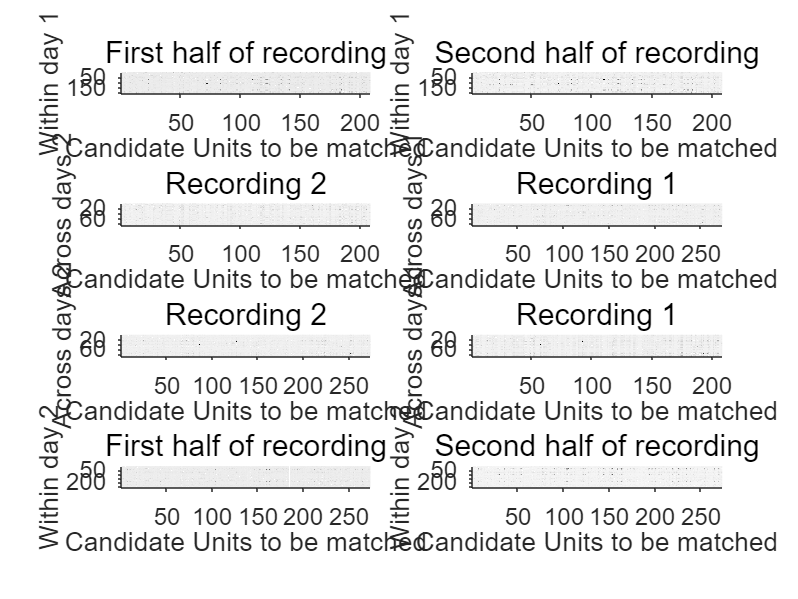

Computing ISI, this will take some time...
Computing FR Differences...
Computing Natural Image Responses...


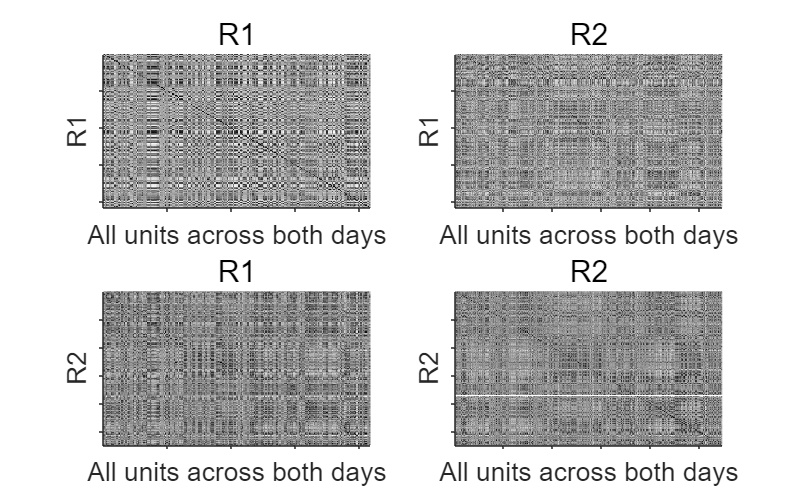


% Evaluating the matching using functional scores (only works when having access to Kilosort output, e.g. spike times etc. )
ComputeFunctionalScores(UMparam.SaveDir)

disp(class(UMparam.SaveDir))

string


disp(UMparam.SaveDir)

C:\Users\klein\OneDrive\summer_intern\tmp


disp(class(['TrackingPerformance ', UMparam.SaveDir]))

string


## You can also visualize the units on the probe:

way2
try
     0     1

days
     0     1

     1
     2



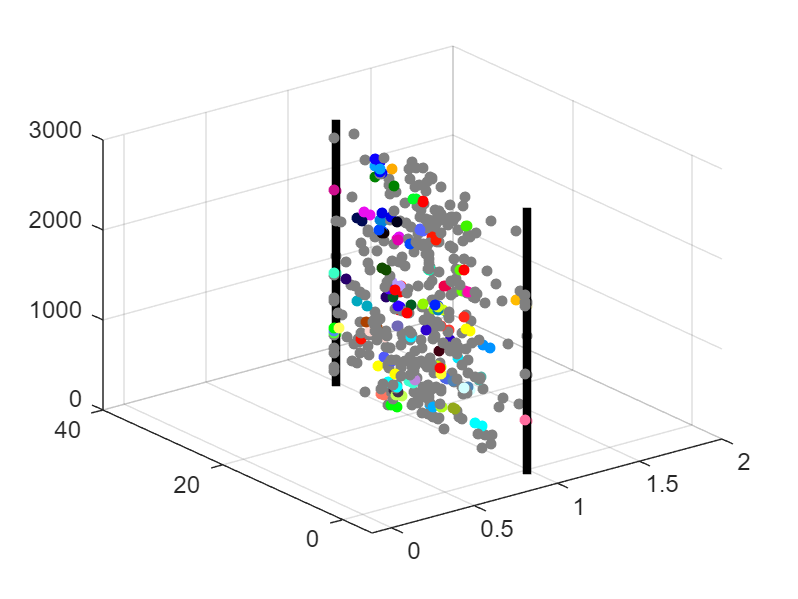

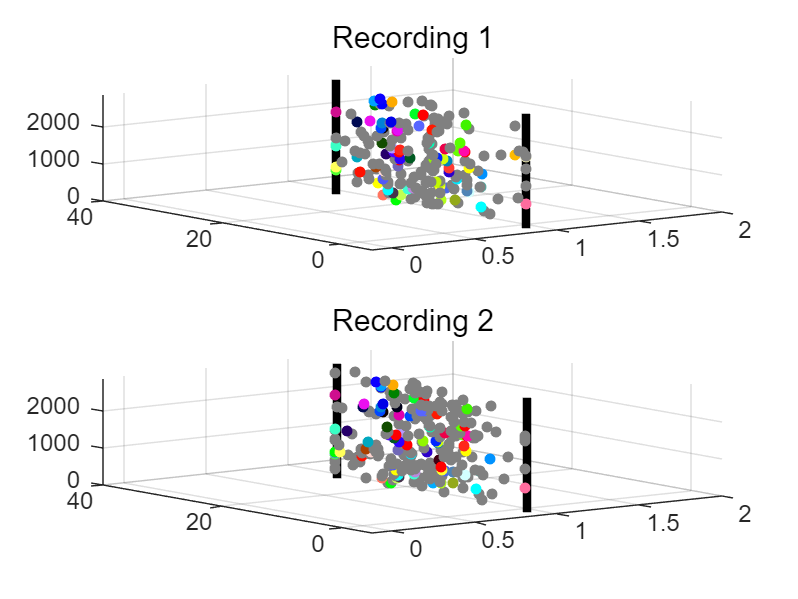

days
     0     1

     1
     2



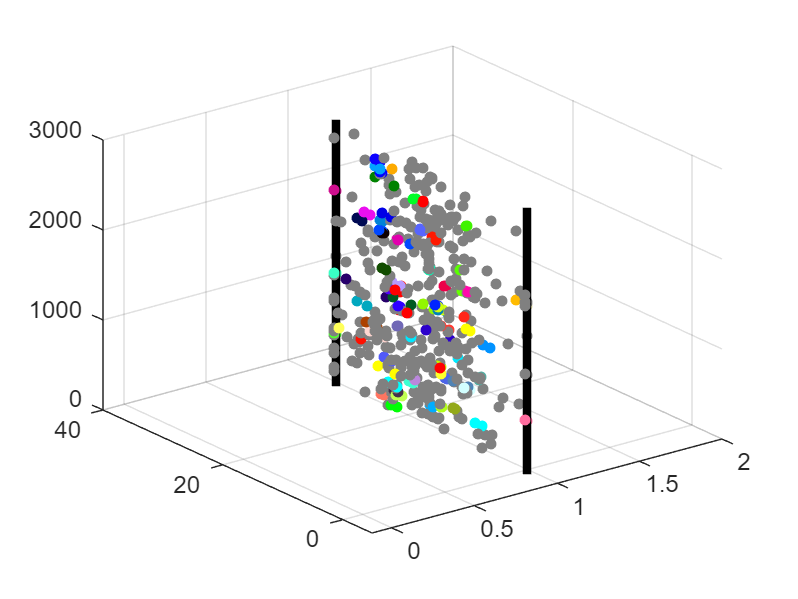

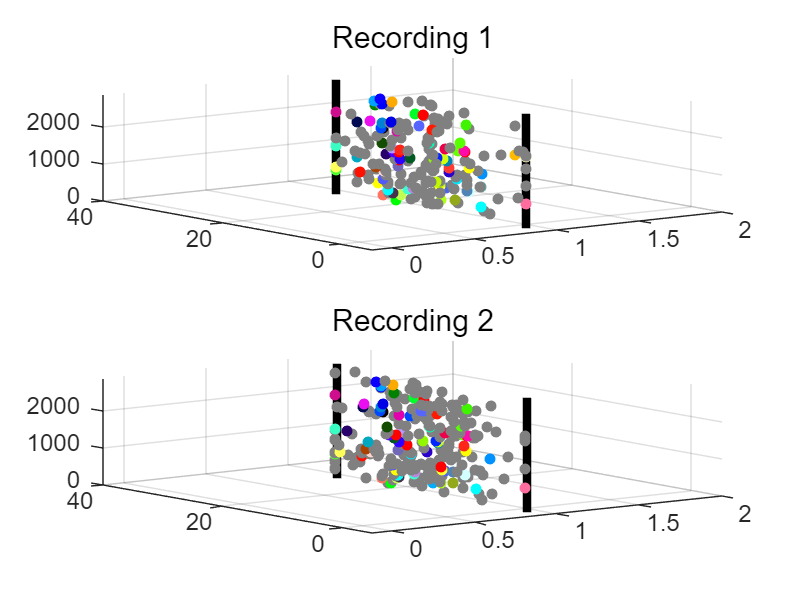

days
     0     1

     1
     2



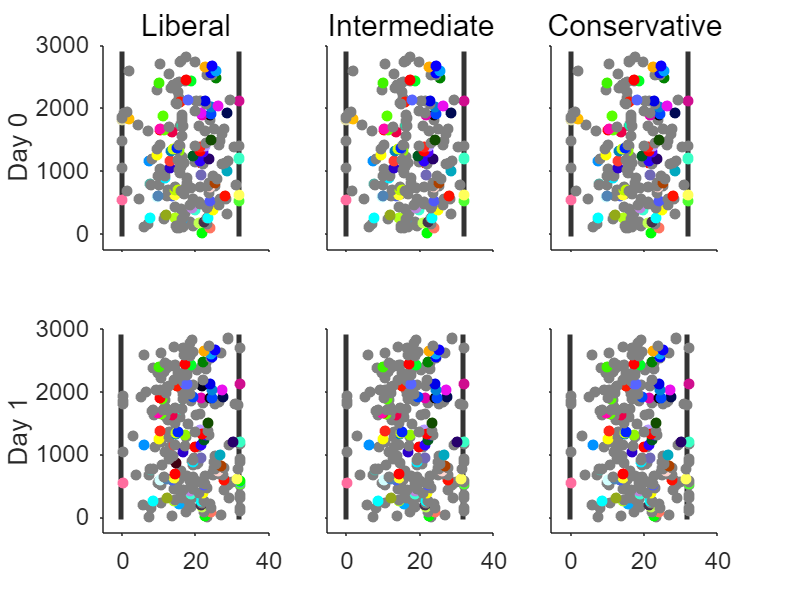

PlotUnitsOnProbe(clusinfo,UMparam,UniqueIDConversion,WaveformInfo)

## Curation:

if UMparam.MakePlotsOfPairs
    DrawPairsUnitMatch(UMparam.SaveDir);
    if UMparam.GUI
        FigureFlick(UMparam.SaveDir)
        pause
    end
end

Loading spike information...
Plotting pairs...
Plotting pairs took 9 minutes for 481 units


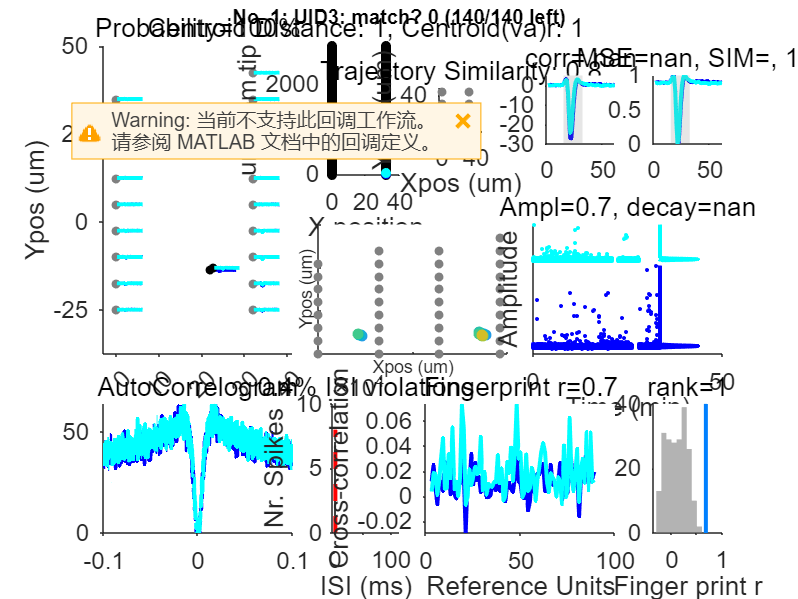

if true
    DrawPairsUnitMatch(UMparam.SaveDir);
    if true
        FigureFlick(UMparam.SaveDir)
        pause
    end
end

if true
    FigureFlick(UMparam.SaveDir)
    pause
end

## If using bombcell

% Evaluating how much quality metrics predict "matchability" (only works in combination with bombcell)
QualityMetricsROCs(UMparam.SaveDir);

## The following scripts work with several animals and plot summaries of the matching evaluation.

UMFiles = {fullfile(UMparam.SaveDir,'UnitMatch.mat')}; % cell containing a list of all the UnitMatch outputs you want to combine -- let's use one for now.
groupvec = 1; % How do you want to group these outputs? E.g., group all the outputs from the same animal into one

% Plots a summary of the functional metrics results
summaryFunctionalPlots(UMFiles, 'Corr', groupvec);

% Plots a summary of the matching probability
summaryMatchingPlots(UMFiles);